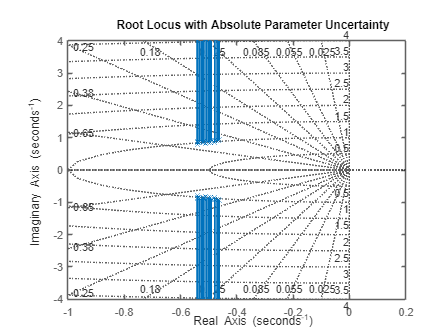

cp = ureal('cp', 1.0, 'Range', [0.9, 1.1]); % 10% uncertainty
cv = ureal('cv', 1.0, 'Range', [0.9, 1.1]); % 10% uncertainty

m = 1.0; % Mass
A = [0, 1; -cp/m, -cv/m];
B = [0; cp/m];
C = [1, 0];
D = 0;

G_unc = uss(A, B, C, D);

figure;
rlocus(G_unc);
grid on;
title('Root Locus with Absolute Parameter Uncertainty');


syms m c_v c_p k
syms delta_omega delta_zeta delta_p delta_v

sre = - c_v / (2*m)

$$sre = -\frac{c_{v}}{2\,m}$$

omega = 1/2 * sqrt(4 * (1 + k) * c_p / m - (c_v / m)^2)

$$omega = \frac{\sqrt{\frac{c_{p}\,\left(4\,k+4\right)}{m}-\frac{{c_{v}}^{2}}{m^{2}}}}{2}$$


zeta = - sre / sqrt(sre^2 + omega^2)

$$zeta = \frac{c_{v}}{2\,m\,\sqrt{\frac{c_{p}\,\left(4\,k+4\right)}{4\,m}}}$$


delta_omega = diff(omega, c_p) * delta_p + diff(omega, c_v) * delta_v

$$delta\_omega = \frac{\delta_{p}\,\left(4\,k+4\right)}{4\,m\,\sqrt{\frac{c_{p}\,\left(4\,k+4\right)}{m}-\frac{{c_{v}}^{2}}{m^{2}}}}-\frac{c_{v}\,\delta_{v}}{2\,m^{2}\,\sqrt{\frac{c_{p}\,\left(4\,k+4\right)}{m}-\frac{{c_{v}}^{2}}{m^{2}}}}$$


delta_zeta = diff(zeta, c_p) * delta_p + diff(zeta, c_v) * delta_v

$$delta\_zeta = \frac{\delta_{v}}{2\,m\,\sqrt{\frac{c_{p}\,\left(4\,k+4\right)}{4\,m}}}-\frac{c_{v}\,\delta_{p}\,\left(4\,k+4\right)}{16\,m^{2}\,{\left(\frac{c_{p}\,\left(4\,k+4\right)}{4\,m}\right)}^{3/2}}$$

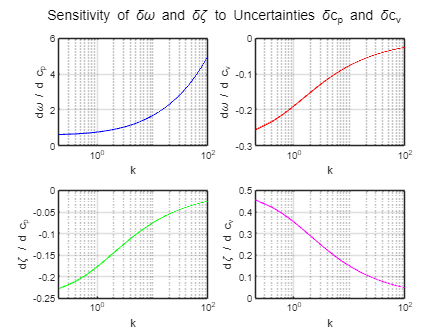

d_omega_d_cp = diff(omega, c_p);
d_omega_d_cv = diff(omega, c_v);
d_zeta_d_cp = diff(zeta, c_p);
d_zeta_d_cv = diff(zeta, c_v);

% Convert symbolic expressions to numerical functions
f_d_omega_d_cp = matlabFunction(d_omega_d_cp, 'Vars', {k, c_p, c_v, m});
f_d_omega_d_cv = matlabFunction(d_omega_d_cv, 'Vars', {k, c_p, c_v, m});
f_d_zeta_d_cp = matlabFunction(d_zeta_d_cp, 'Vars', {k, c_p, c_v, m});
f_d_zeta_d_cv = matlabFunction(d_zeta_d_cv, 'Vars', {k, c_p, c_v, m});

% Define parameter values
c_p_val = 1;  % Set unit value for c_p
c_v_val = 1;  % Set unit value for c_v
m_val = 1;    % Set unit value for m
k_vals = linspace(0, 100, 500); % Range of k values

% Compute derivative values over k
d_omega_d_cp_vals = f_d_omega_d_cp(k_vals, c_p_val, c_v_val, m_val);
d_omega_d_cv_vals = f_d_omega_d_cv(k_vals, c_p_val, c_v_val, m_val);
d_zeta_d_cp_vals = f_d_zeta_d_cp(k_vals, c_p_val, c_v_val, m_val);
d_zeta_d_cv_vals = f_d_zeta_d_cv(k_vals, c_p_val, c_v_val, m_val);

% Plot the results
figure;

subplot(2,2,1);
plot(k_vals, d_omega_d_cp_vals, 'b', 'LineWidth', 1);
set(gca, 'XScale', 'log')
grid on;
xlabel('k');
ylabel('d\omega / d c_p');

subplot(2,2,2);
plot(k_vals, d_omega_d_cv_vals, 'r', 'LineWidth', 1);
set(gca, 'XScale', 'log')
grid on;
xlabel('k');
ylabel('d\omega / d c_v');

subplot(2,2,3);
plot(k_vals, d_zeta_d_cp_vals, 'g', 'LineWidth', 1);
set(gca, 'XScale', 'log')
grid on;
xlabel('k');
ylabel('d\zeta / d c_p');

subplot(2,2,4);
plot(k_vals, d_zeta_d_cv_vals, 'm', 'LineWidth', 1);
set(gca, 'XScale', 'log')
grid on;
xlabel('k');
ylabel('d\zeta / d c_v');

sgtitle('Sensitivity of \delta\omega and \delta\zeta to Uncertainties \deltac_p and \deltac_v');
print(gcf, 'figures/u_propagation.png', '-dpng', '-r300');